# **LQRコントローラを同期発電機に付加する！**

今回扱うIEEE68busモデルには母線1~16に発電機が接続されています

ここでは．これらの発電機に分散的にLQR制御器を付加してみて，応答がどのように変化するか観察してみます．

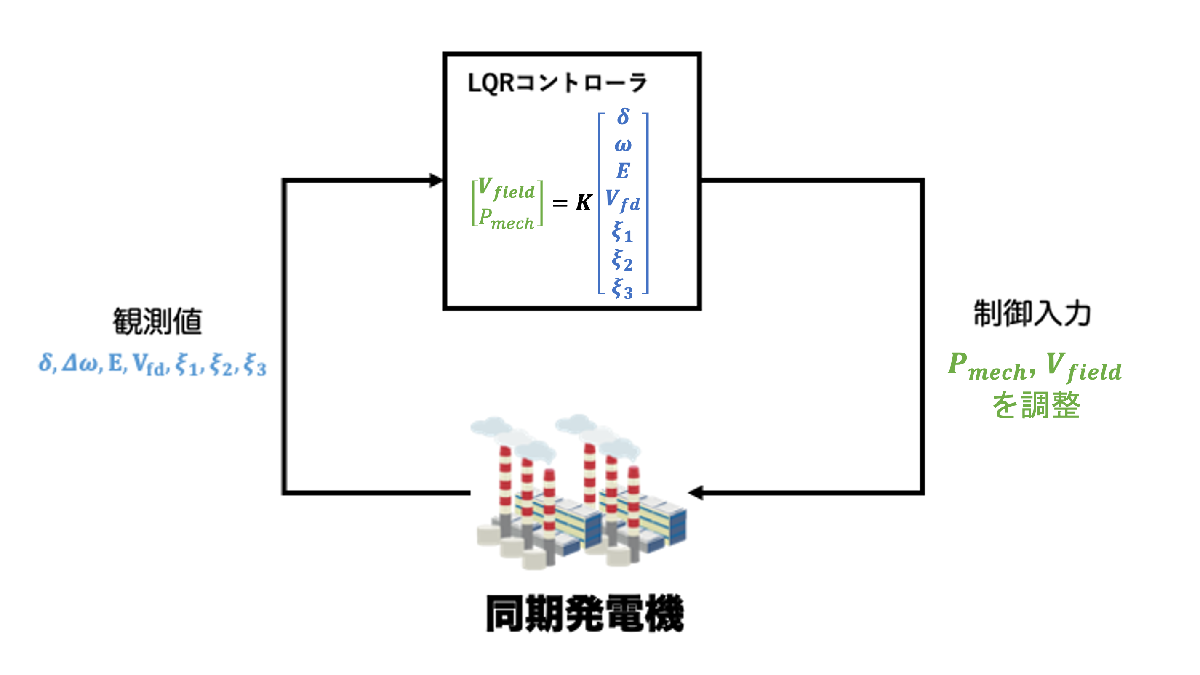

### 同期発電機の１軸モデル

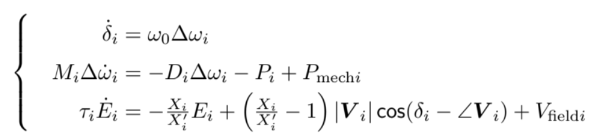

これに加えて同期発電機には，AVRやPSSと呼ばれる制御器が付加されています．

これらの制御器には，それぞれ以下の状態を持ちます．

AVRの状態として : $V_{\textrm{fd}}$

PSSの状態として：$\xi_1 \;,\xi {\;}_{2\;} \;,\xi_{3\;}$

つまり同期発電機モデル１つにつき，以下の７つの状態が存在します．

### 
$$X=\left\lbrack \delta \;,\Delta \;\omega \;,E,V_{\textrm{fd}\;} ,{\;\xi \;}_1 ,\xi_{2\;} ,\xi {\;}_{3\;} \right\rbrack \;$$


これらの状態に対して，重みを指定します

***状態に対する評価関数：　***$\left\lbrack \delta \;,\Delta \;\omega \;,E,V_{\textrm{fd}\;} ,{\;\xi \;}_1 ,\xi_{2\;} ,\xi {\;}_{3\;} \right\rbrack \;\;\left\lbrack \begin{array}{ccccccc}
Q_1  & 0 & 0 & 0 & 0 & 0 & 0\\
0 & Q_2  & 0 & 0 & 0 & 0 & 0\\
0 & 0 & Q_3  & 0 & 0 & 0 & 0\\
0 & 0 & 0 & Q_4  & 0 & 0 & 0\\
0 & 0 & 0 & 0 & Q_5  & 0 & 0\\
0 & 0 & 0 & 0 & 0 & Q_6  & 0\\
0 & 0 & 0 & 0 & 0 & 0 & Q_7 
\end{array}\right\rbrack \;\;\;\;\left\lbrack \begin{array}{c}
\delta \;\\
\omega \;\\
E\\
V_{\textrm{fd}\;} \\
\xi_1 \\
\xi_2 \\
\xi_3 
\end{array}\right\rbrack$

また，今回の演習では同期発電機の$\left\lbrack P_{\textrm{mech}} ,V_{\textrm{field}} \right\rbrack$に入力を加えます．

この入力に対しても重みを指定します

***入力に対する評価関数：　***$\left\lbrack \begin{array}{cc}
P_{\textrm{mech},}  & V_{\textrm{field}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
R_{1\;}  & 0\\
0 & R_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
P_{\textrm{mech}} \\
V_{\textrm{field}} 
\end{array}\right\rbrack$

LQRコントローラでは上の２つの評価関数の和を最小化するゲインKを決定します．

# **制御器を付加した電力系統の作り方**

では，実際にシミュレーション上で制御器を付加した系統の作成方法を解説します

おおまかなステップは以下の３stepです，

## **Step1**

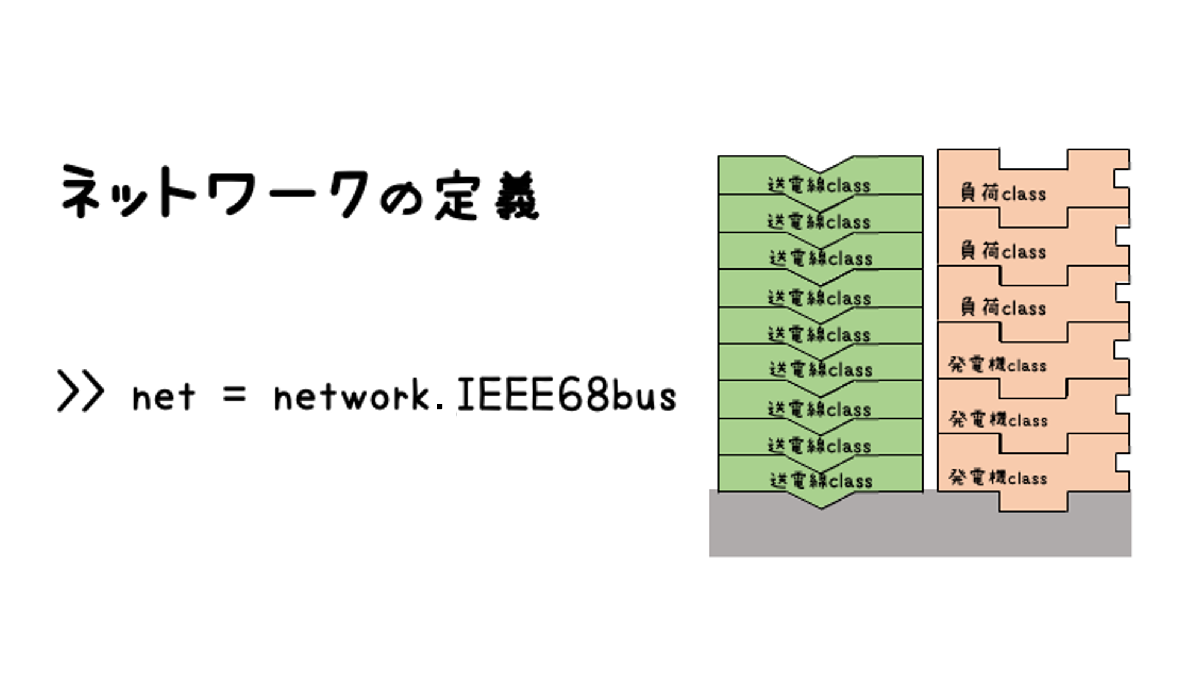

### Step2

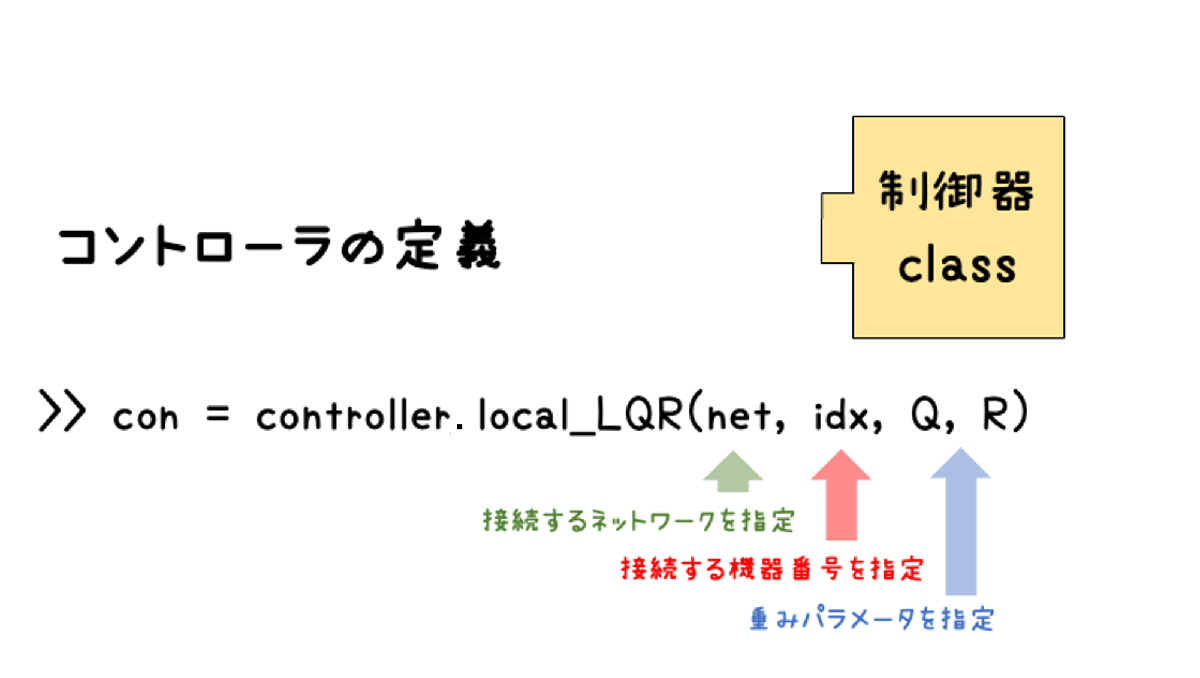

## Step3

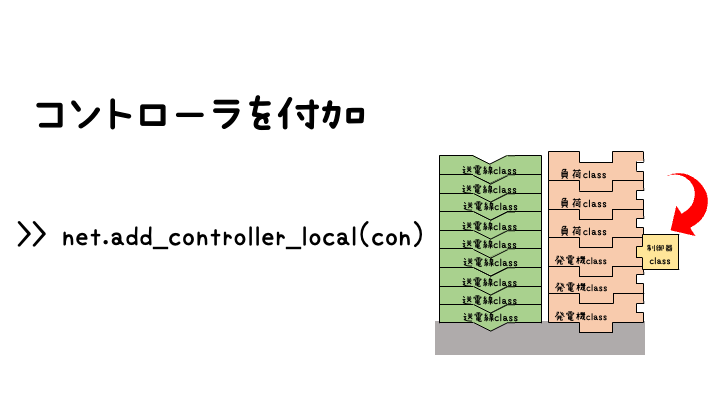

例えば母線１に接続されている発電機にLQRコントローラを付加したい場合は以下のようにして定義できます！

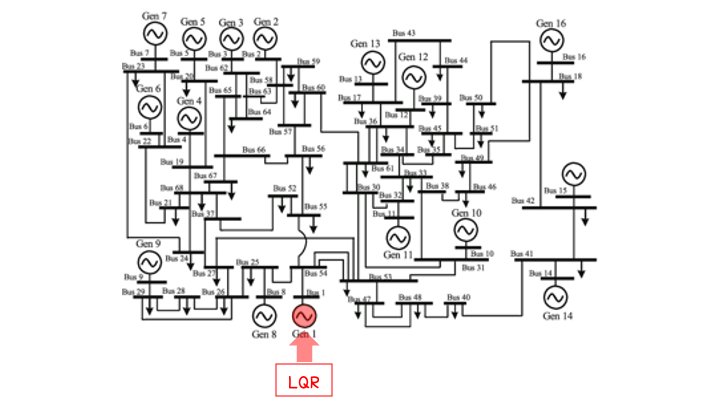

# **シミュレーション**

以降では，制御器の付加の仕方によって応答がどのように変化するかを考えます．

比較のためシミュレーションは，

- シミュレーション時間：0〜10秒

- 地絡発生：母線１に0〜0.1秒の間地絡が発生

という条件に統一します．

まずは比較対象のために制御器を付加しない場合についてシミュレーションを行っておきます．

 
net = network.IEEE68bus;

%地絡応答でテスト
time = [0, 25];
fault = {{[1,1.07],1}};
out = net.simulate(time,'fault',fault);


 Simulation Start !!
 
0s                                                                                                25s
|        10%       20%       30%       40%       50%       60%       70%       80%       90%        |
|---------o---------o---------o---------o---------o---------o---------o---------o---------o---------|
|>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>|


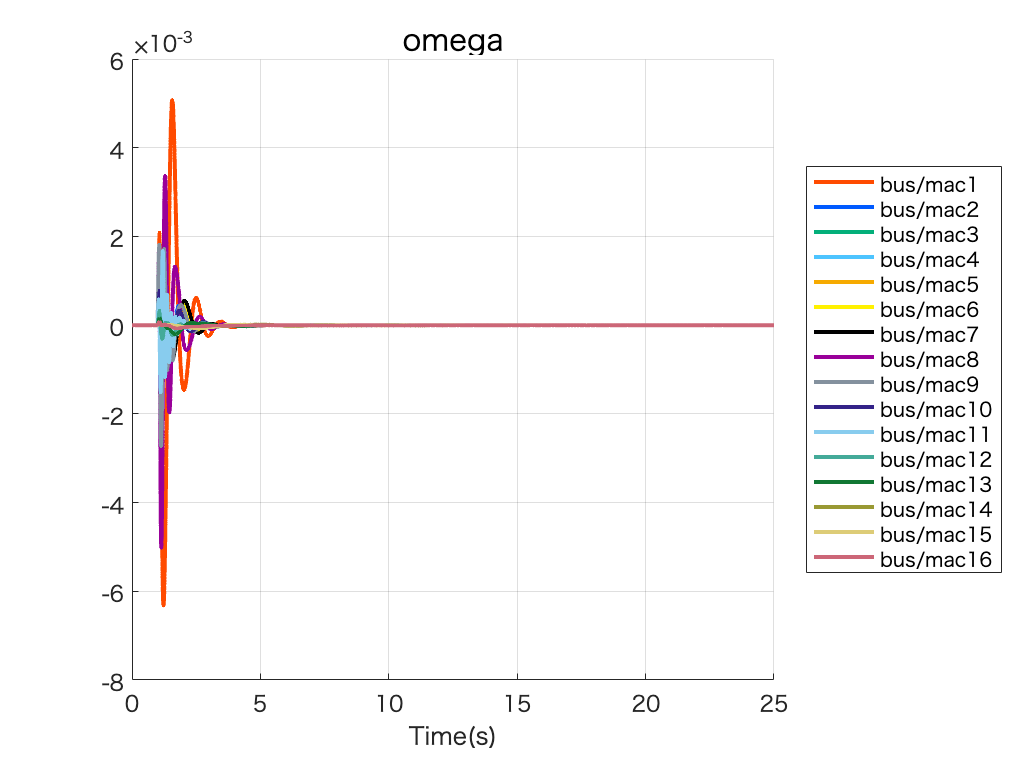

out.plot('para', 'omega')

L2= culculate_l2norm(out);


各発電機の周波数偏差のL２ノルム(大きい順) 

同期発電機01のl2ノルム: 0.0033206
同期発電機08のl2ノルム: 0.001844
同期発電機09のl2ノルム: 0.00095253
同期発電機04のl2ノルム: 0.00081198
同期発電機06のl2ノルム: 0.00065647
同期発電機07のl2ノルム: 0.00065073
同期発電機02のl2ノルム: 0.00062614
同期発電機03のl2ノルム: 0.00060885
同期発電機11のl2ノルム: 0.00059788
同期発電機05のl2ノルム: 0.0005692
同期発電機10のl2ノルム: 0.00036356
同期発電機12のl2ノルム: 0.00014898
同期発電機13のl2ノルム: 0.00013449
同期発電機15のl2ノルム: 7.1014e-05
同期発電機14のl2ノルム: 6.3736e-05
同期発電機16のl2ノルム: 6.3218e-05
 
全発電機のL２ノルムの和：0.011483


# **LQRコントローラを付加したシミュレーション **

**コード例 : （例えば発電機iに付加したい場合）**

**まとめて追加したい場合for文を用いるのも良いでしょう！**

**明らかに発散してそうであれば，画面上方にある「停止」ボタンでシミュレーションを止めれます．**

 
net = network.IEEE68bus;

%%%%%%%%%%%%%%%%%%% ここで制御器を追加します %%%%%%%%%%%%%%%%%%%
idx=1;                                                     % 発電機1に制御器を付加する
Q  = [1e-5, 1e3, 1e-5, 1e-5, 1e-5, 1e-5, 1e-5];            % Qを定義
R  = [1e-9, 1e-9];                                         % Rを定義
LQR = controller.local_LQR(net, idx, diag(Q), diag(R));    % LQRコントローラモデルを定義
net.add_controller_local(LQR)                              % 制御器モデルを付加

%地絡応答でテスト
time = [0, 25];
fault = {{[1,1.07],1}};
out = net.simulate(time,'fault',fault);


 Simulation Start !!
 
0s                                                                                                25s
|        10%       20%       30%       40%       50%       60%       70%       80%       90%        |
|---------o---------o---------o---------o---------o---------o---------o---------o---------o---------|
|>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>>|


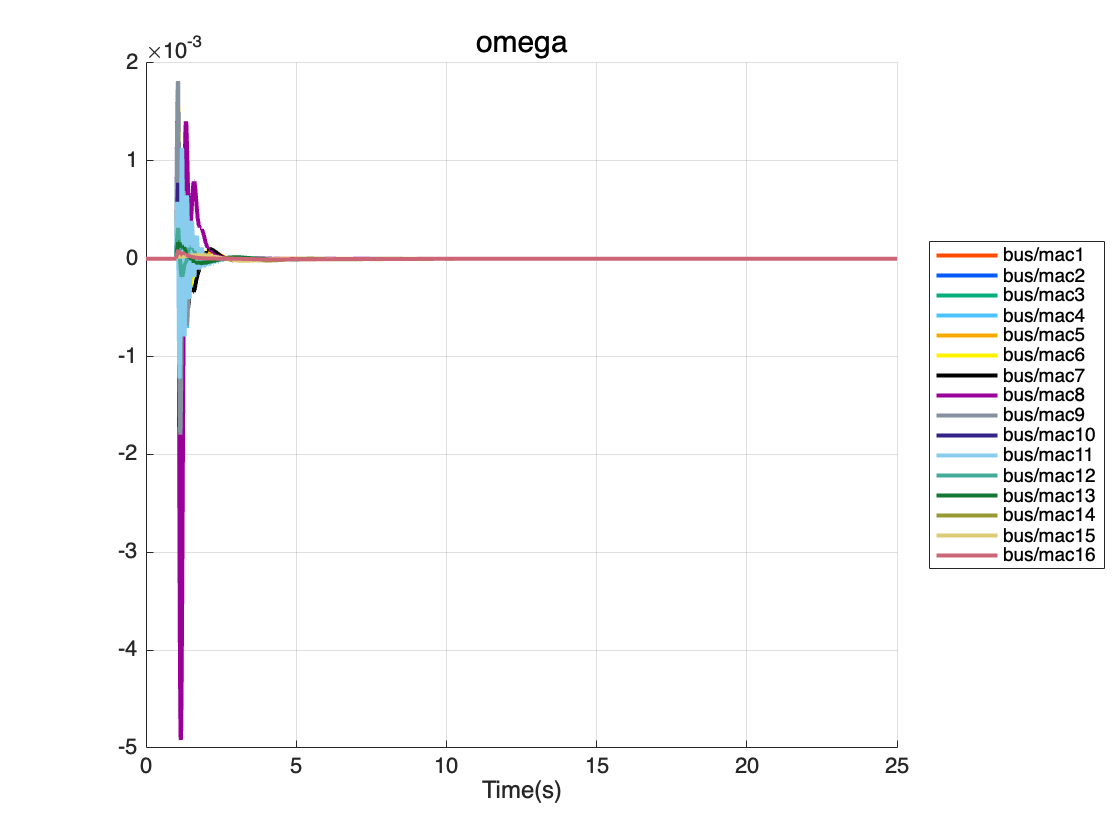

out.plot('para', 'omega')

culculate_l2norm(out);


各発電機の周波数偏差のL２ノルム(大きい順) 

同期発電機08のl2ノルム: 0.0015654
同期発電機09のl2ノルム: 0.00062388
同期発電機04のl2ノルム: 0.00052865
同期発電機07のl2ノルム: 0.00046151
同期発電機11のl2ノルム: 0.00043793
同期発電機06のl2ノルム: 0.00043566
同期発電機02のl2ノルム: 0.00042469
同期発電機03のl2ノルム: 0.00039335
同期発電機05のl2ノルム: 0.00036904
同期発電機10のl2ノルム: 0.00026999
同期発電機12のl2ノルム: 0.00010437
同期発電機13のl2ノルム: 7.9554e-05
同期発電機15のl2ノルム: 4.0422e-05
同期発電機16のl2ノルム: 3.7115e-05
同期発電機14のl2ノルム: 3.697e-05
同期発電機01のl2ノルム: 7.3861e-07
 
全発電機のL２ノルムの和：0.0058093


# **まとめ**

## 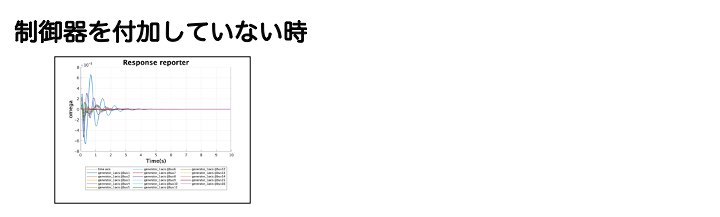

## 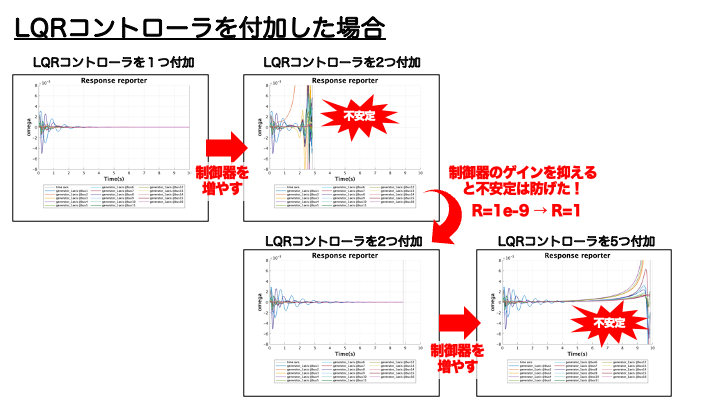

## 関数定義

function L2 = culculate_l2norm(out)
    L2 = zeros(1,16);                       %データ格納用の行列を定義
    fprintf('\n各発電機の周波数偏差のL２ノルム(大きい順) \n\n')
    for i = 1:16                            %IEEE68busは母線1~16に同期発電機が付加されている．
        omega_i  = out.X{i}{:,'omega'};     %母線iの周波数偏差の応答データを抽出
        omega2_i = omega_i.^2;              %応答データの各要素を２乗する
        integer  = trapz(out.t, omega2_i);  %２乗したデータを数値積分する
        L2_i     = sqrt(integer);           %積分値の平方根を取りL２ノルムを計算
        L2(i)    = L2_i;                    %得られたL2ノルムを配列に格納する
    end
    [~, idx_sort] = sort(L2,'descend');     %L2ノルムの大きい順にソートした機器の番号を得る
    
    for i = idx_sort
        disp(['同期発電機',num2str(i,'%.2d'),'のl2ノルム: ',num2str(L2(i))])
    end
    disp(' ')
    disp(['全発電機のL２ノルムの和：',num2str(sum(L2))])
end
